# SVD

## Intro

### Definition and uses

#### Uses:

**Solve lin system.**

Ax = b, nonsquare A

Takes highly complex data, and distills it, to eigenvectors.

#### Definition

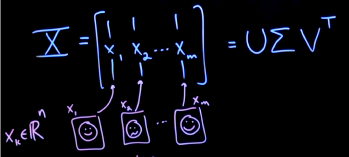

Will decompose a matrix into 3 others.

U, orthogonal, sigma, diagonal, and 

Both U, and V are unitary, meaning that they are all columns are orthogonal, and have a unit length. And can completely represent R_n.

So its transpose is its inverse.

The eigenvalues in U, are in decreasing importance towards representing the data X. 

Therefore the sigma values are in nonincreasing order. And sigma_1 is therefore the largest.

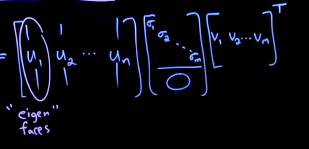

V tells you the exact mixture of eigenfaces that would represent each specific face.But v1, represents the use of u1, in each consecutive face.

The first column of them all represent the combination of the U vectors.

### Computation

Given some data matrix, X.

In our example we take faces shaped into n sized vectors.

m = 4;
n = 10;
X = randi(10, n, m);
[U, sigma, V] = svd(X);
size(V)

ans =      4     4


disp(X)

     9     1     8     4
     8    10     3     9
     2     7     1     8
     6    10     8     9
     4     2     7     6
     6    10     8     7
     4     8     7    10
     5     6     5     5
     2     5     4     1
     3     3     9     9



disp(U)

  Columns 1 through 6

   -0.2615    0.6383    0.4377    0.3250   -0.3643   -0.0473
   -0.3825   -0.3642    0.3610    0.4853    0.2380    0.0315
   -0.2422   -0.4470   -0.2503    0.3019   -0.2612    0.0013
   -0.4236   -0.0957    0.0187   -0.2188    0.0225   -0.5891
   -0.2405    0.3459   -0.2056    0.0916    0.8140    0.0332
   -0.3946   -0.0677    0.1935   -0.4285   -0.0342    0.7361
   -0.3787   -0.0988   -0.3305   -0.0174   -0.0981    0.0122
   -0.2651   -0.0011    0.1899   -0.0655   -0.0237   -0.0843
   -0.1509   -0.0258    0.2090   -0.5682    0.0020   -0.3114
   -0.3118    0.3411   -0.5886    0.0181   -0.2606    0.0506

  Columns 7 through 10

    0.0294   -0.1459    0.0491   -0.2598
    0.0316   -0.1329    0.2108    0.4841
   -0.4295    0.0091    0.1624   -0.5555
   -0.1075   -0.2278   -0.5928    0.0285
   -0.1259    0.0113    0.0779   -0.2934
   -0.1195   -0.1282   -0.2069   -0.0459
    0.8261   -0.0254    0.1182   -0.1745
   -0.0093    0.9372   -0.0552    0.0127
   -0.1063   -

disp(U * sigma) % represents economy U, the only needed ones.

  -10.3062    6.6253    3.0180    1.6669
  -15.0769   -3.7807    2.4895    2.4892
   -9.5445   -4.6397   -1.7259    1.5484
  -16.6954   -0.9939    0.1289   -1.1221
   -9.4804    3.5906   -1.4177    0.4698
  -15.5530   -0.7029    1.3345   -2.1976
  -14.9248   -1.0251   -2.2788   -0.0891
  -10.4486   -0.0117    1.3095   -0.3358
   -5.9464   -0.2681    1.4408   -2.9141
  -12.2876    3.5404   -4.0587    0.0927



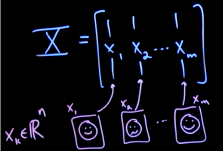

**Some things to know:**

Because n is way larger than m, only the first n U vectors are important to representing X.

The final representation of X is such

Notice the 0 is formed by the 0 sigma values once m eigenvectors are used. After that for the rest of the n rows of sigma there is all zeros.

Actually giving you this equality to X.

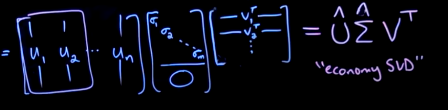

Because of this we can use an economy SVD instead.

m = 4;
n = 10;
X = randi(10, n, m);
[U, sigma, V] = svd(X, 'econ');
norm(U(:, 1)) % see how they are all unit vectors.

ans = 1.0000

disp(X)

     7     2     3     7
     4     8     4     1
    10     4     1    10
     3     9     7     9
     7     8     2     8
     7     6     1     9
     4     2     8     4
     2    10     4     7
     1     3     7     6
     5    10     4     6



disp(U)

   -0.2637   -0.3284    0.2858   -0.1326
   -0.2284    0.2935   -0.2619   -0.6771
   -0.3642   -0.5863    0.0534   -0.0367
   -0.3944    0.3232    0.1086    0.3327
   -0.3652   -0.1556   -0.2352   -0.0292
   -0.3415   -0.3160   -0.1350    0.1797
   -0.2221    0.1632    0.6059   -0.4079
   -0.3362    0.3217   -0.2664    0.3345
   -0.2252    0.2608    0.4920    0.2669
   -0.3564    0.1886   -0.2852   -0.1710



disp(U * sigma) % See how it isn't resized, just properly scaled.

   -9.5163   -3.7135    2.4812   -0.7025
   -8.2429    3.3184   -2.2731   -3.5883
  -13.1453   -6.6294    0.4637   -0.1944
  -14.2356    3.6541    0.9423    1.7630
  -13.1800   -1.7591   -2.0419   -0.1546
  -12.3270   -3.5730   -1.1716    0.9522
   -8.0160    1.8452    5.2597   -2.1619
  -12.1359    3.6374   -2.3121    1.7728
   -8.1280    2.9489    4.2707    1.4146
  -12.8648    2.1328   -2.4753   -0.9065



So another way to say it, is that matrix X is approximated by these products. Which at the end of the day is an addition of several rank 1 matrices.

With each addition, the approximatoin of X improves. Think about it, the last sigmas are really small, so they don't really change anything.

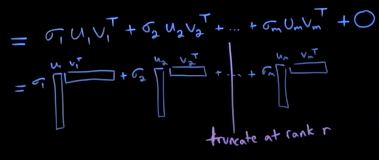

Defining r at some arbitrary sigma value when it becomes too small, then it is just a good approximation to the amount you requested.

#### Ways to calculate U and V

Check Lin alg notebook.

#### SVD example

BasicFace = imread()